# Generate figure1 of the paper "Choice of trimming proportion and number of clusters in robust clustering based on trimming"  

### Luis A. García-Escudero, Christian Hennig, Agustin Mayo Iscar,  Gianluca Morelli, Marco Riani,  

Remark: we assume that you have FSDA installed, at least version 8.7.7.6

In order to install FSDA, in the Home menu click on Add-Ons and search for FSDA.

## Data loading

% Load the GHMMR dataset and make sure that FSDA installed
try 
    load GHMMR.mat
catch
    error('FSDA:missingFSDA','FSDA toolbox version at least 8.7.7.6 is not installed from Get Add-Ons')
end

Y = table2array(GHMMR(:,1:2));

### Left panel of Figure 1

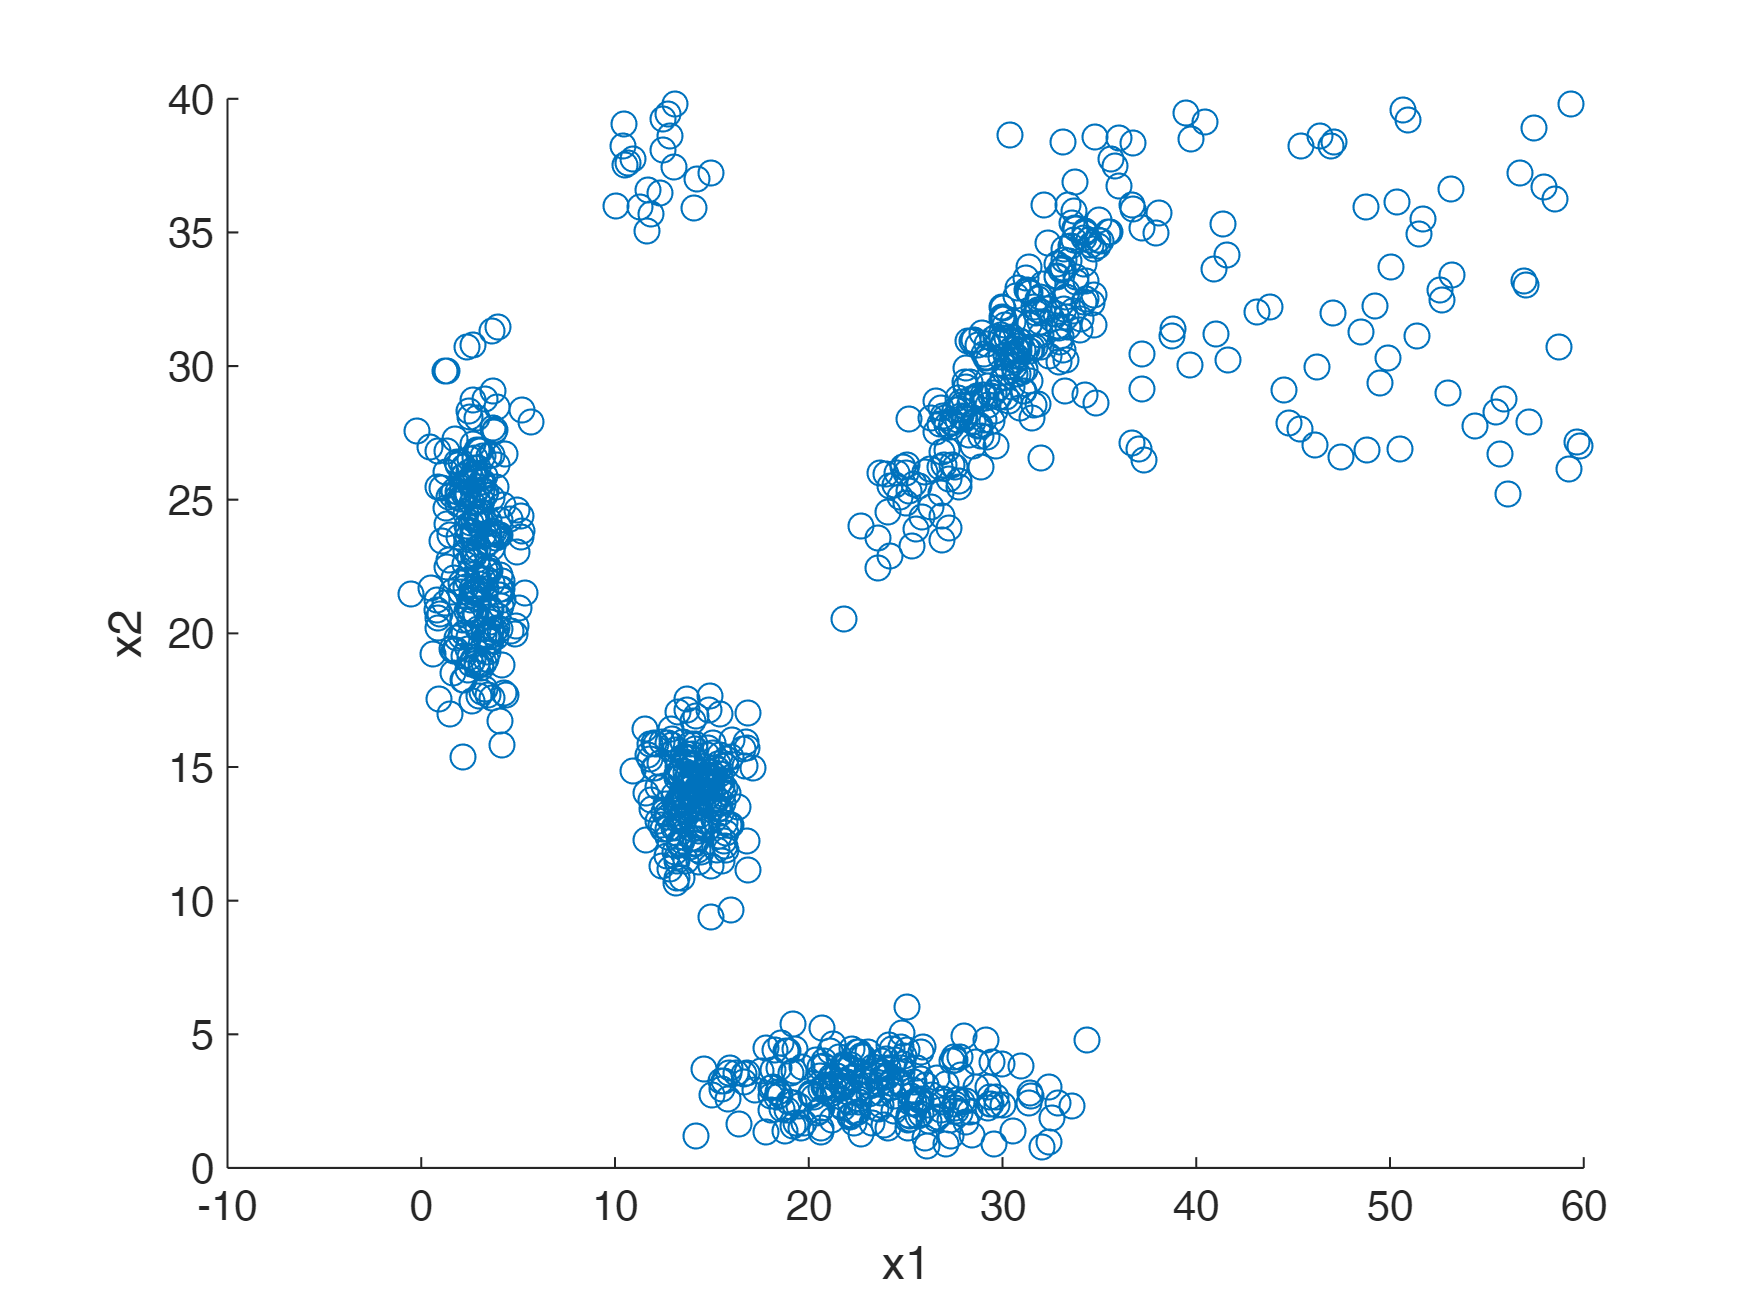

% Check the version of FSDA which is installed 
% (it must be at least 8.7.7.6)
try
    scatter(GHMMR,"x1","x2")
catch
    error('FSDA:oldFSDA','FSDA toolbox is installecd but you need version at least 8.7.7.6')
end

### Call to function ctlcurves and creation of right panel of Figure 1

k = 1:7; % number of groups to test
alphaTrim = 0.00:0.025:0.2; % level of trimming to test
cc = 50; % restriction factor
nsamp =  1000; % number of  subsets to extract for each k and alpha
    
[outCTL] = ctlcurves(Y, 'alpha',alphaTrim,'kk',k, 'restrfactor',cc, 'nsamp',nsamp,'bands','');

k=1
k=2
k=3
k=4
k=5
k=6
k=7


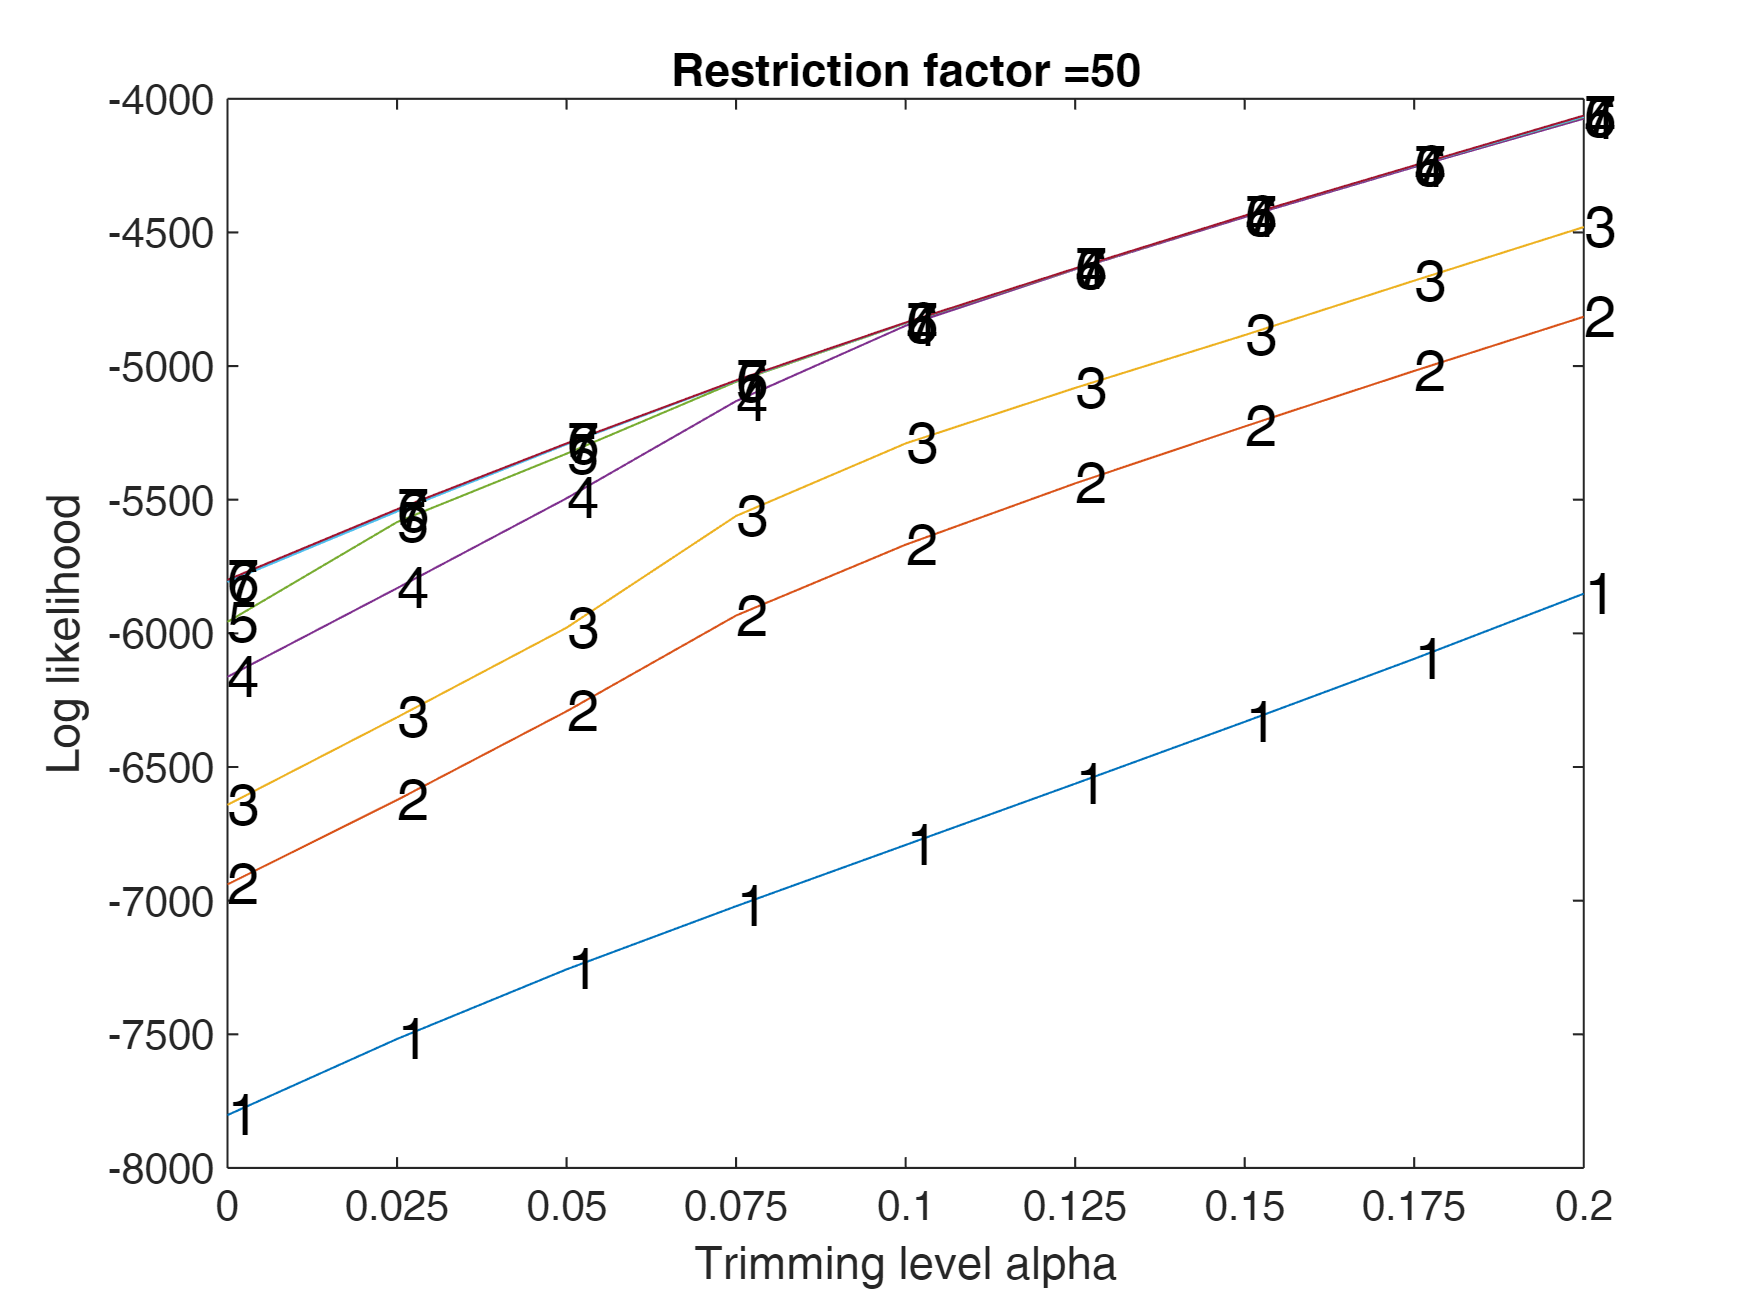

title(['Restriction factor =' num2str(cc)])